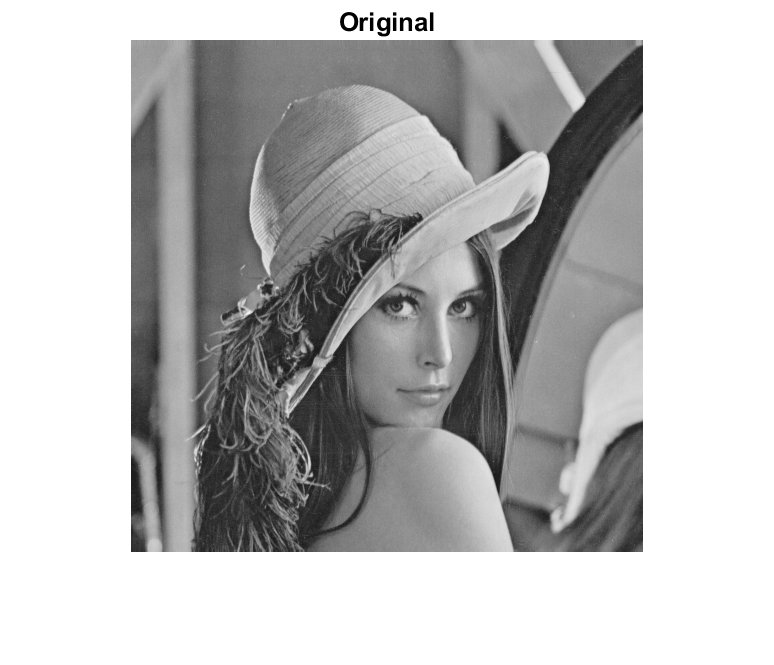

clear 
close all

img = im2double(imread('BM3D_images/Lena512.png'));

% define a blurring filter
h = fspecial('motion',30,40);

% define the image size
[Mi,Ni] = size(img);
[Mh,Nh] = size(h);
M = Mi + Mh - 1;
N = Ni + Nh - 1;

% corrupt the image
z = conv2(img,h,'full');

% show the corrupted and the original image
figure, imshow(img), title('Original')

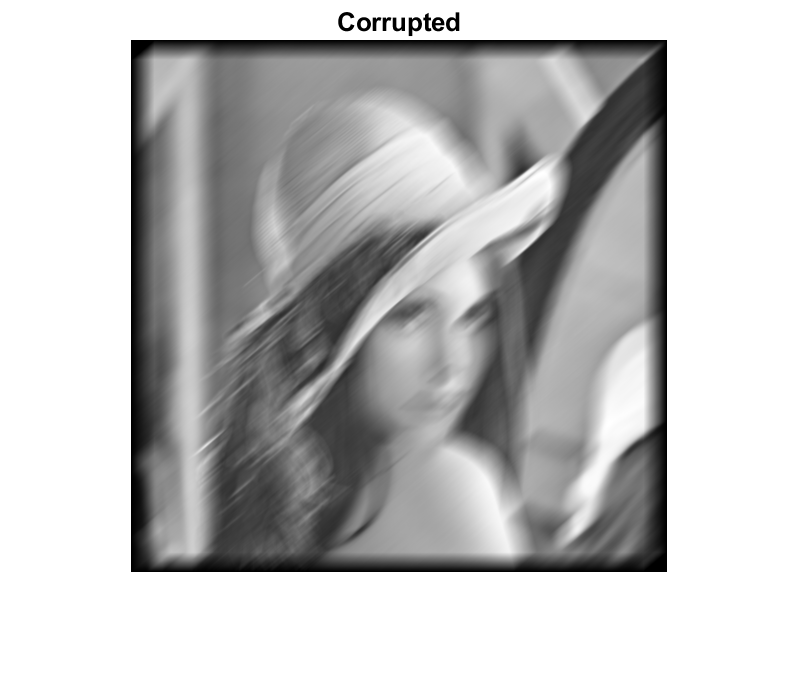

figure, imshow(z,[]), title('Corrupted')

## Blur inversion

compute the fourier transform of the noisy image with padding

z_f = fft2(z,M,N);

% compute the fourier transform of the blurring filter with padding
h_f = fft2(h, M, N);

% Invert the blur in fourier domain
img_hat_f = z_f./h_f;

% invert the fourier transform
img_hat = ifft2(img_hat_f, 'symmetric');
img_hat = img_hat(1:Mi, 1:Ni);

% compute the PSNR
psnr_inv = 10 * log10((Mi * Ni)/sum((img_hat - img).^2, 'all'))

psnr_inv = 242.2376

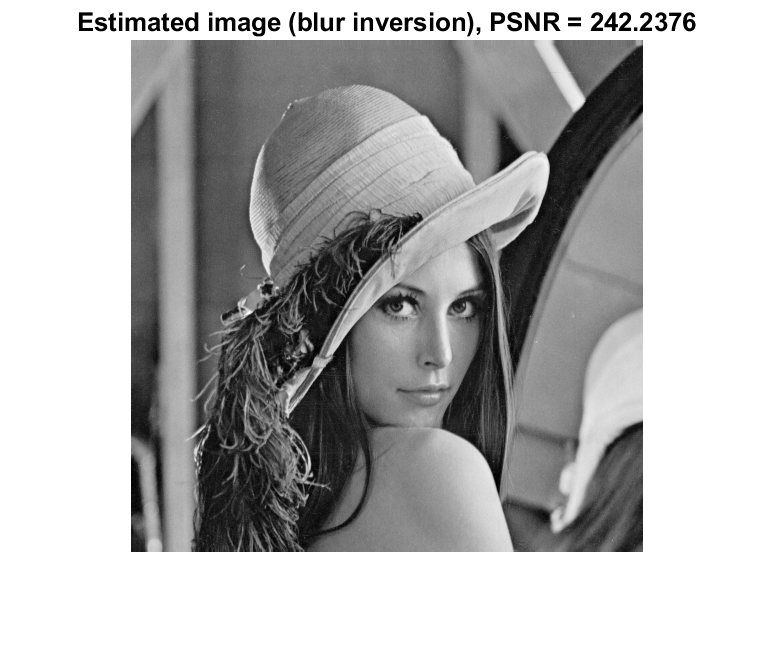


% show the estimated image
figure, imshow(img_hat, [])
title(['Estimated image (blur inversion), PSNR = ', num2str(psnr_inv)]);

## Adding the noise

% start with a very small amount of noise
sigma_noise = 40/255;
% corrupt the image
noise = random('normal', 0, sigma_noise, size(img));

z = conv2(img + noise,h,'full');


%z = z + noise;

% compute the fourier transform of the noisy image with padding
z_f = fft2(z, M, N);
% compute the fourier transform of the blurring filter with padding
h_f = fft2(h, M, N);
noise_f = fft2(noise, M, N);

% Invert the blur in fourier domain
img_hat_f = z_f./h_f; %- noise_f./h_f; %
% we dont actually know the noise so it's not legal to use it 

% invert the fourier transform
img_hat = ifft2(img_hat_f, 'symmetric');
img_hat = img_hat(1:Mi, 1:Ni);

% compute the PSNR
psnr_inv = 10 * log10((Mi * Ni)/sum((img_hat - img).^2, 'all'))

psnr_inv = 16.0856

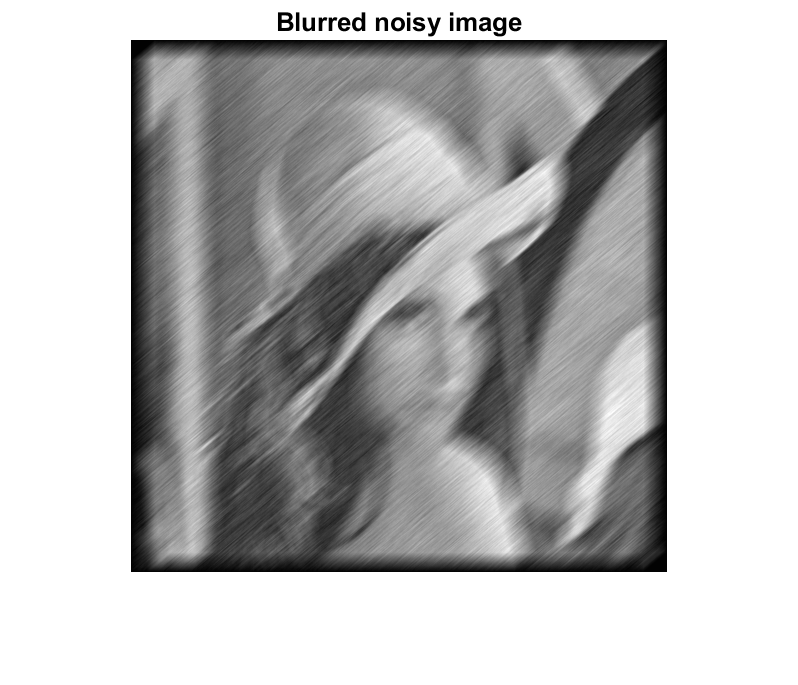

%Blurred noisy image
figure, imshow(z, [])
title('Blurred noisy image');

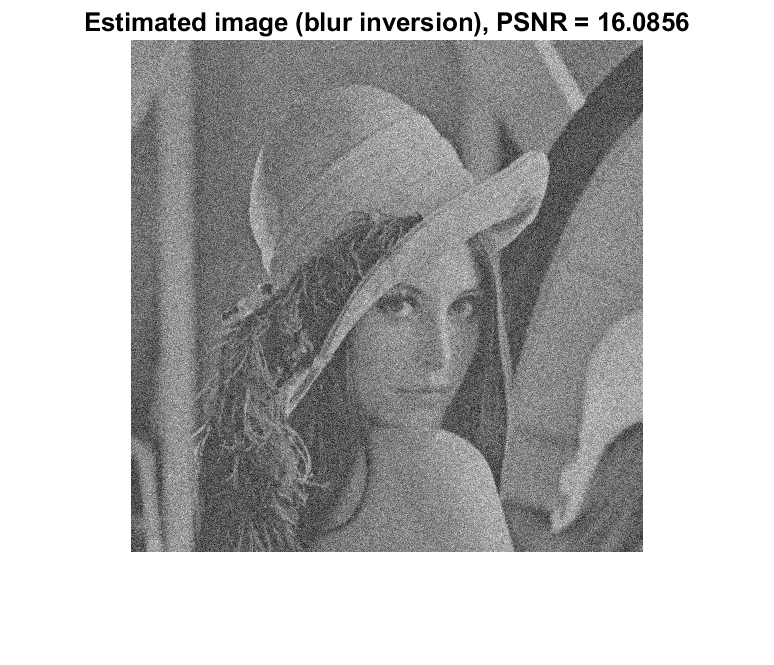

% show the estimated image
figure, imshow(img_hat, [])
title(['Estimated image (blur inversion), PSNR = ', num2str(psnr_inv)]);

## use the regularized inverse

% set a small regularization parameters
lambda = 1e-2;
% compute the regularized inverse
% Z = S - N
img_hat_f = z_f.*conj(h_f)./(h_f.*conj(h_f) + lambda); 

% invert the fourier transfor
img_hat = ifft2(img_hat_f, 'symmetric');
img_hat = img_hat(1:Mi, 1:Ni);

% compute the PSNR
psnr_reg = 10 * log10((Mi * Ni)/sum((img_hat - img).^2, 'all'))

psnr_reg = 23.5545

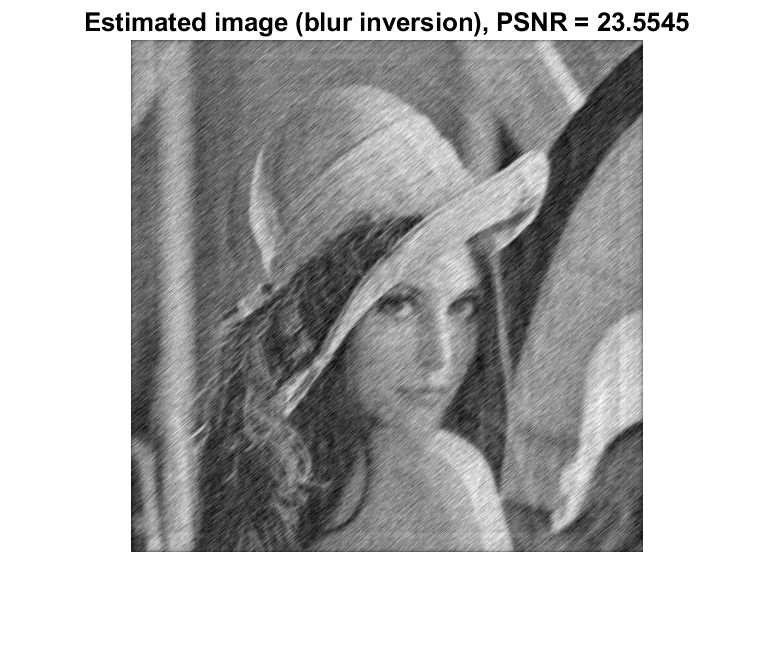


% show the estimated image
figure, imshow(img_hat, [])
title(['Estimated image (blur inversion), PSNR = ', num2str(psnr_reg)]);



% try to increase the noise level:
sigma_noise = 20/255;

% larger noise requires larger regularization parameters